# **Curve Fitting**

## Fitting Data with a Polynomial

There is an intrinsic function for polynomials in MATLAB called [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html).  See the example:

%Second order polynomials (e.g. a*x^2+b*x^1+c*x^0) with a=1, b=2, c=3

%x is equal to 2 in this case
polyval([1 2 3],2)

ans = 11


%Same polynomial written out in long form
1*2^2+2*2^1+3*2^0

ans = 11


%General form for any x
p2gen=@(x)polyval([1 2 3],x)

p2gen = function_handle with value:
    @(x)polyval([1,2,3],x)


p2gen(2)

ans = 11

## Curve Fitting with Polynomials

[`Polyfit`](https://www.mathworks.com/help/matlab/ref/polyfit.html) is a function used to fit linear data or data that can be fit with a higher order polynomial.

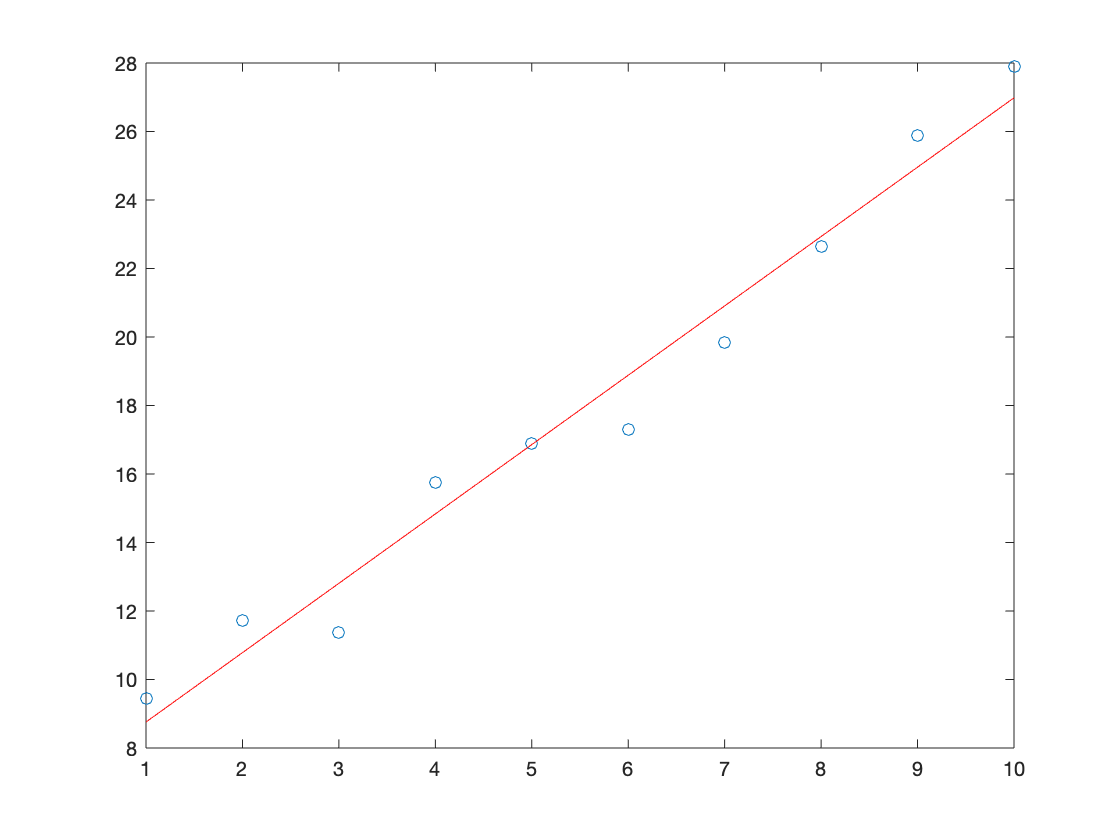

clear all;

%Generate some noisy linear data
modelfunc=@(x)2*x+5;
xvals=1:10;
noisydata=rand(1,length(xvals))*3+modelfunc(xvals);

%Fit the data with a 1st order polynomial (also known as a line)
n=1; %Define order of polynomial

%Fit data with polyfit, p is a array of the coefficients of the polynomial 
%or the values multiplying each x^n term
p=polyfit(xvals,noisydata,n);  

%Use polyval to evaluate that polynomial found by polyfit at the same
%x-values as the data
fitline=polyval(p,xvals);      

%Plot both the data and the fit
plot(xvals,noisydata,'o',xvals,fitline,'r');

## **Using the Curve-Fitting Toolbox**

Let’s load some sample data (download from Canvas):

load reactiondata.mat

We are going to use the Curve Fitting App (included in the Curve Fitting Toolbox) to fit this data two different ways.

First we will try to fit the data with an equation that should describe how the reaction rate, *k*, depends on the temperature, *T*.  We will fit the data to determine the coefficients, A, b, and Ea.  Each of these coefficients tells us something abou the reaction.  For example, Ea is the activation energy.

                                                          
$$k=AT^b e^{\left(-\frac{E_a }{\left(\textrm{RT}\right)}\right)}$$


Here R=8.314 J/mole/K.

Next we will try to fit this equation with a simplier version (or at least a version that will be simpler for the algorithm to fit).

                                                            
$$k=e^{\left(C+\mathrm{bln}\left(T\right)-\frac{D}{T}\right)}$$


Take a moment to convince yourself that this is the same equation as the first one, just a different form. We will find C, b, and D.  These constants are directly related to A, b, and Ea.

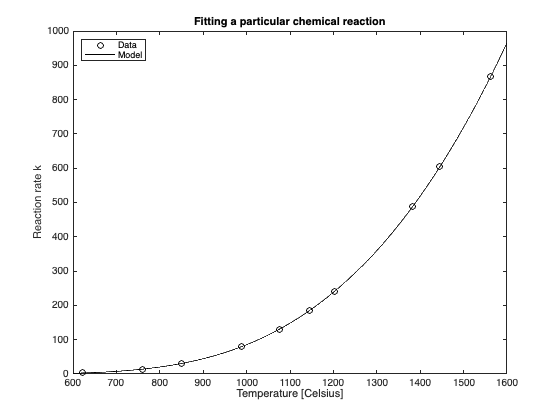

% define constants
R = 8.314;

% save curve fit outputs
C = -5.677;
D = 3918;
b = 2.033;

% calculate original coefficients
A = exp(C);
Ea = D*R;

% define fit points
T = 600 : 1600;
kfit = A .* T.^b .* exp(-Ea ./ (R .* T));

% plot with original equation
plot(temperature, k, "ok")
hold on
plot(T, kfit, "-k")
hold off
xlabel("Temperature [Celsius]")
ylabel("Reaction rate k")
title("Fitting a particular chemical reaction")
xlim([600, 1600])
legend("Data", "Model", Location="northwest")
exportgraphics(gcf, "model_fit.png")